# Getting amplitude, power, and power density from an FFT

This script was developed to demonstrate the concepts that are covered in the MATLAB Tech Talk on Power Spectrum and Power Spectral Density. We start with the FFT of a time signal with two dominant sinusoids. From that, we scale it to create the amplitude spectrum, the power spectrum, and the power spectral density. 

Additional resources:

Equivalent Noise Bandwidth - [https://www.mathworks.com/help/signal/ref/enbw.html](https://www.mathworks.com/help/signal/ref/enbw.html) 

Peridogram - [https://www.mathworks.com/help/signal/ref/periodogram.html](https://www.mathworks.com/help/signal/ref/periodogram.html) 

Signal Analyzer App - [https://www.mathworks.com/help/signal/ug/using-signal-analyzer-app.html](https://www.mathworks.com/help/signal/ug/using-signal-analyzer-app.html) 

## Create time signal

fs = 500;
t = 0:1/fs:5-1/fs;
freq = 0:fs/length(t):fs-1/fs;
A = [1 4];      % Amplitude
f = [100; 110]; % Frequency

xn = A*sin(2*pi*f*t);
N = length(xn); % Number of samples

## Amplitude Spectrum from FFT

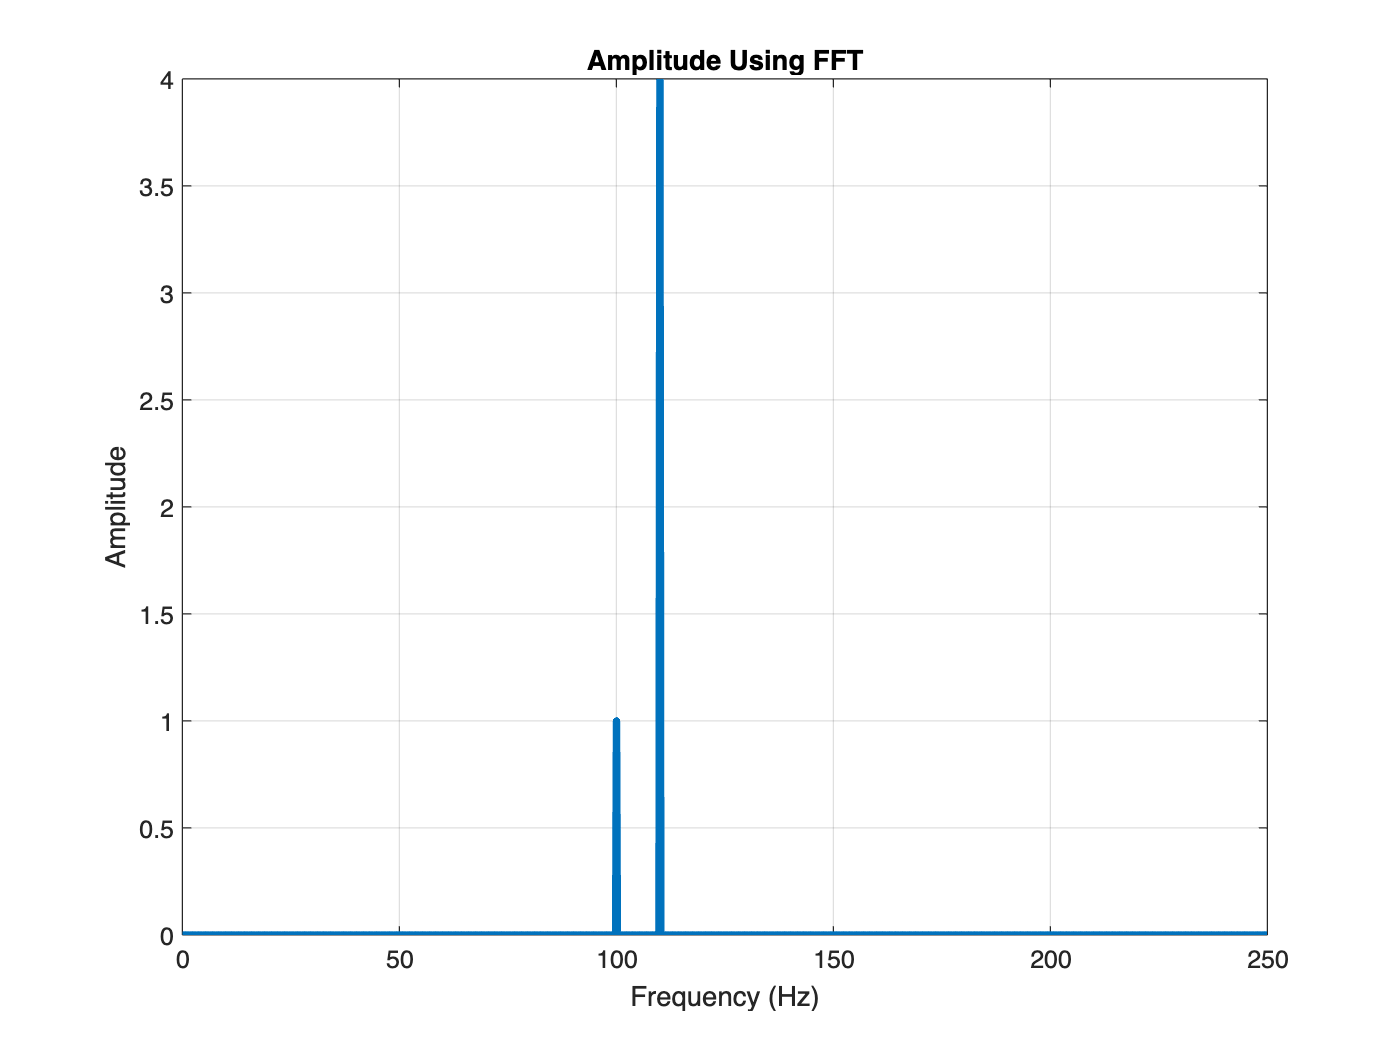

xk = abs(fft(xn))/N; % Two-sided amplitude
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),xk, 'LineWidth', 3)
grid on
title("Amplitude Using FFT")
xlabel("Frequency (Hz)")
ylabel("Amplitude")

## Power Spectrum from FFT

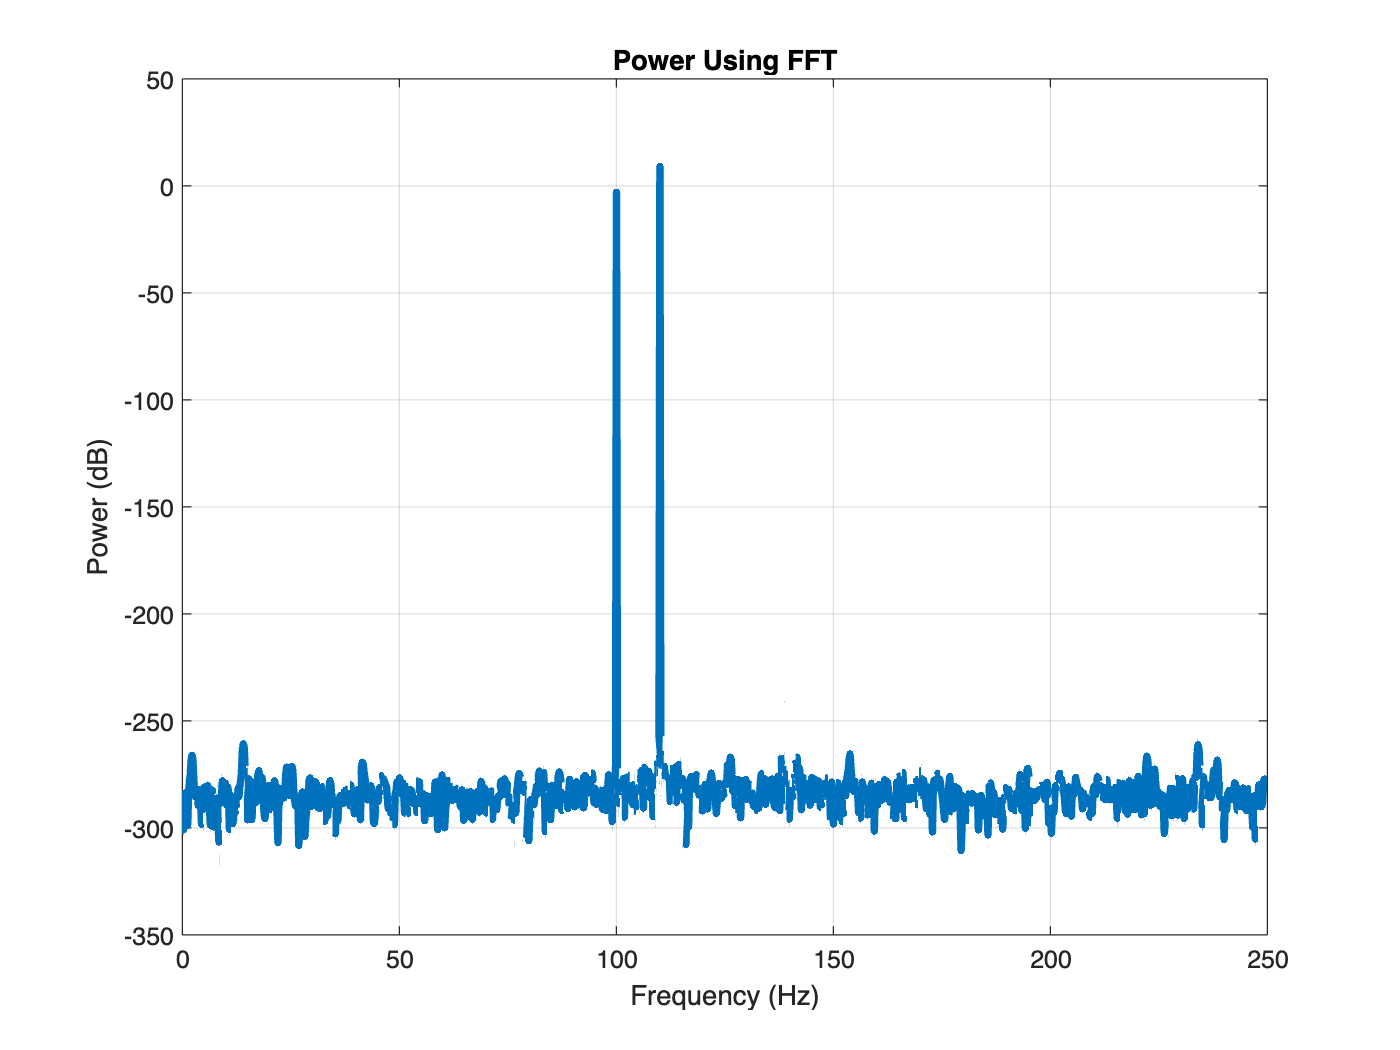

xk = (1/N^2)*abs(fft(xn)).^2; % Two-sided power
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),pow2db(xk), 'LineWidth', 3)
grid on
title("Power Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")

This is exactly what the periodogram function produces.

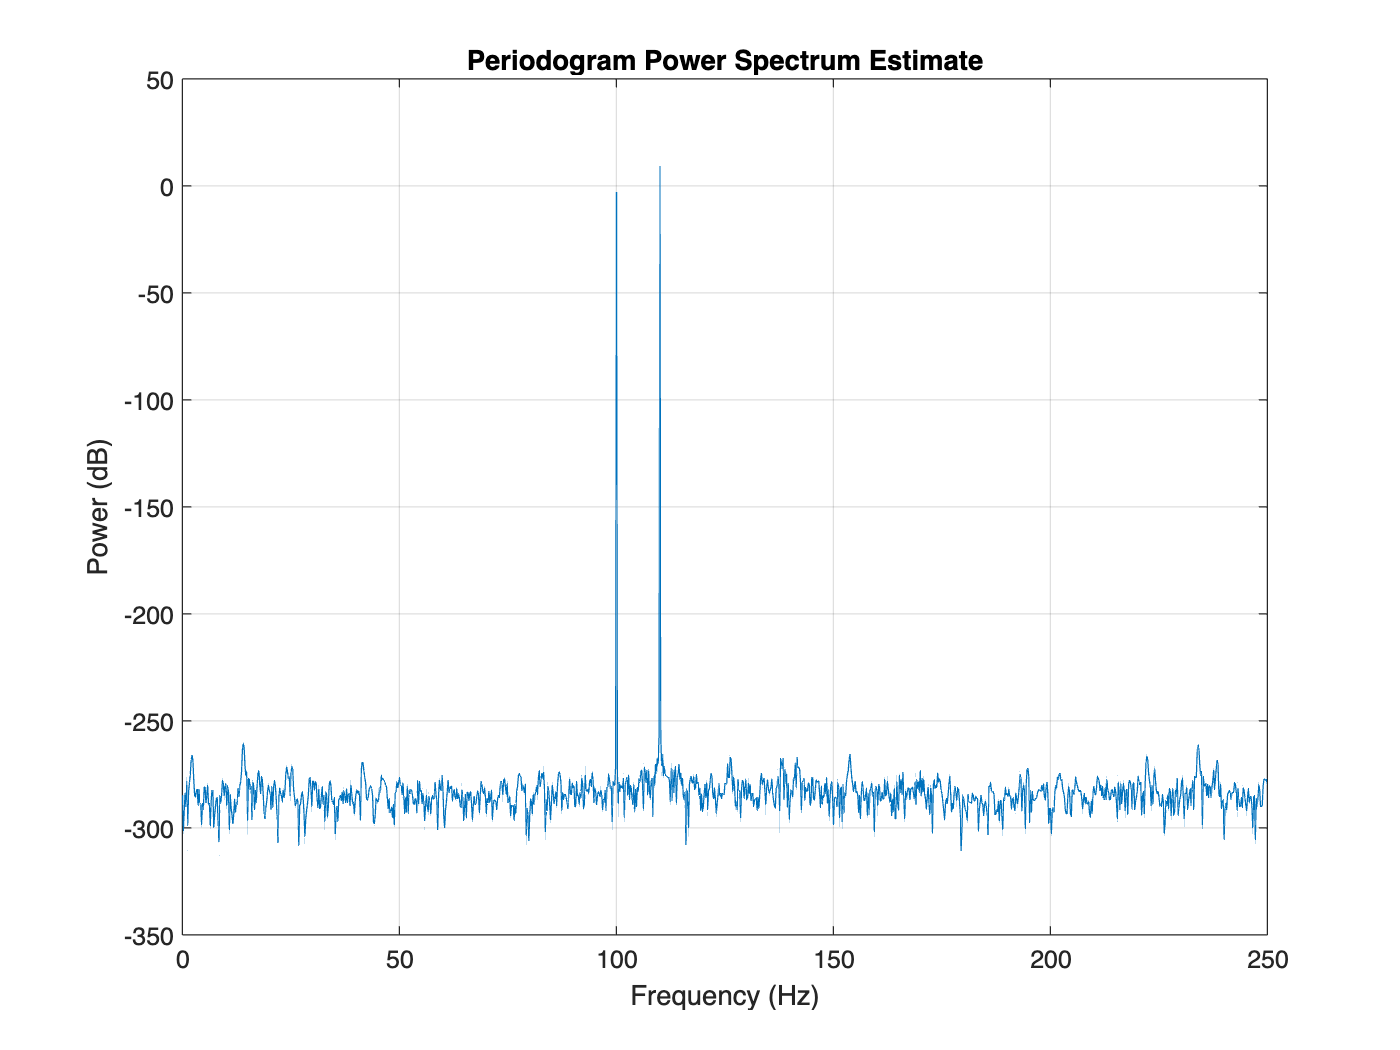

periodogram(xn, rectwin(length(xn)), length(xn), fs, 'power')

Periodogram also takes into account the window and the FFT length when calaculating power. Notice the peak power is the same dispite using a Hamming window and a longer length FFT (zero padded).

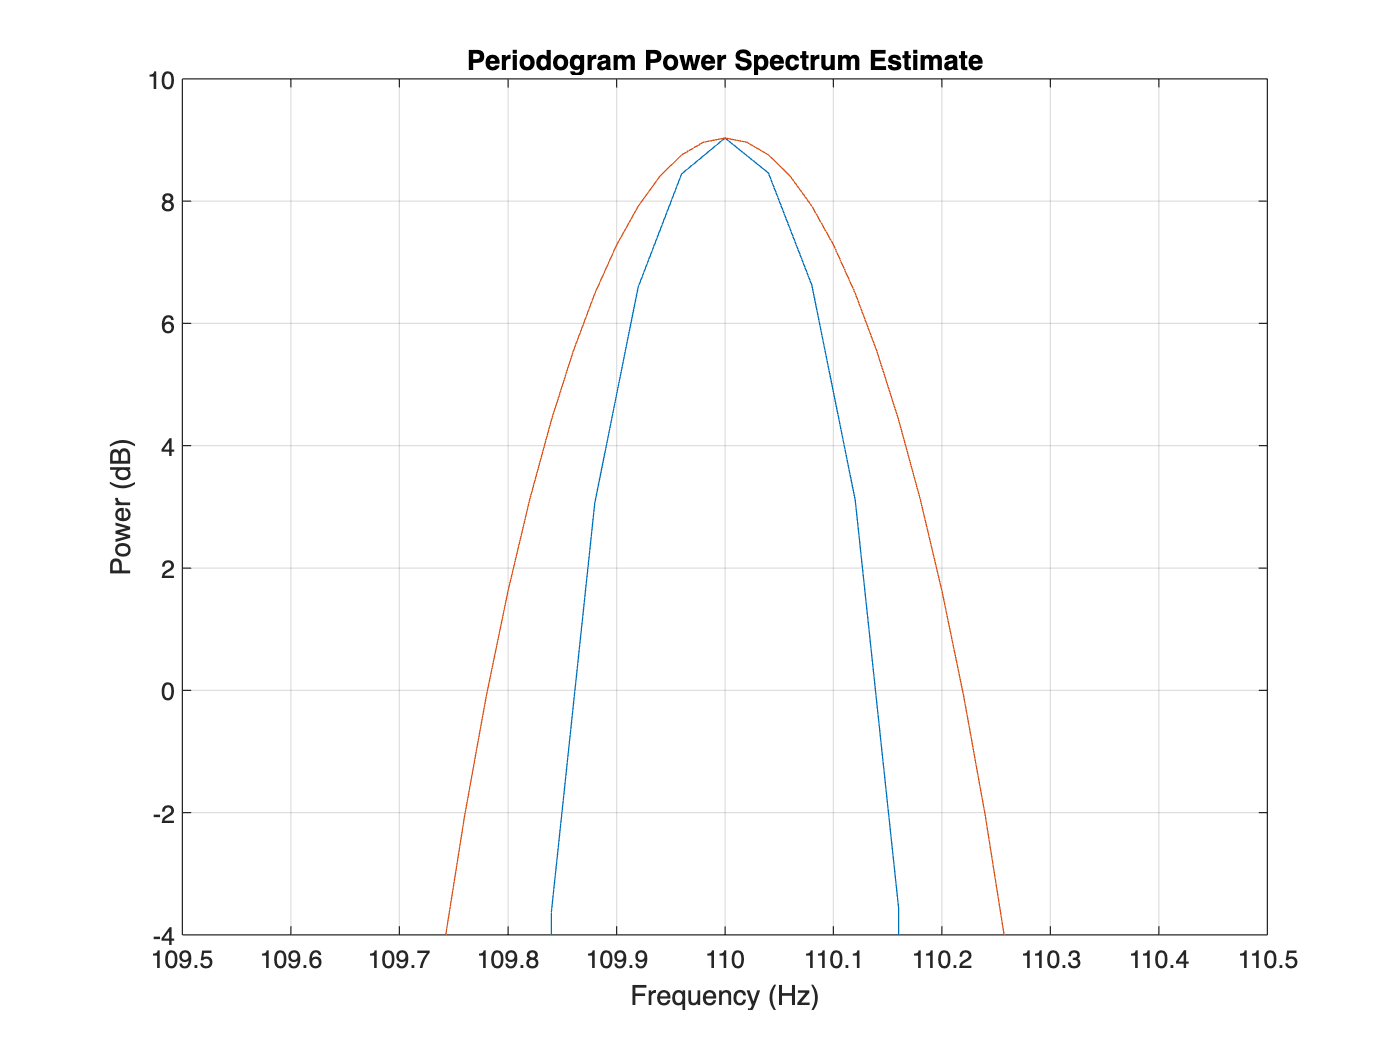

figure
periodogram(xn, rectwin(length(xn)), length(xn)*5, fs, 'power')
hold on
periodogram(xn, hamming(length(xn)), length(xn)*10, fs, 'power')
axis([109.5, 110.5, -4, 10])

## Power Spectral Density from the FFT

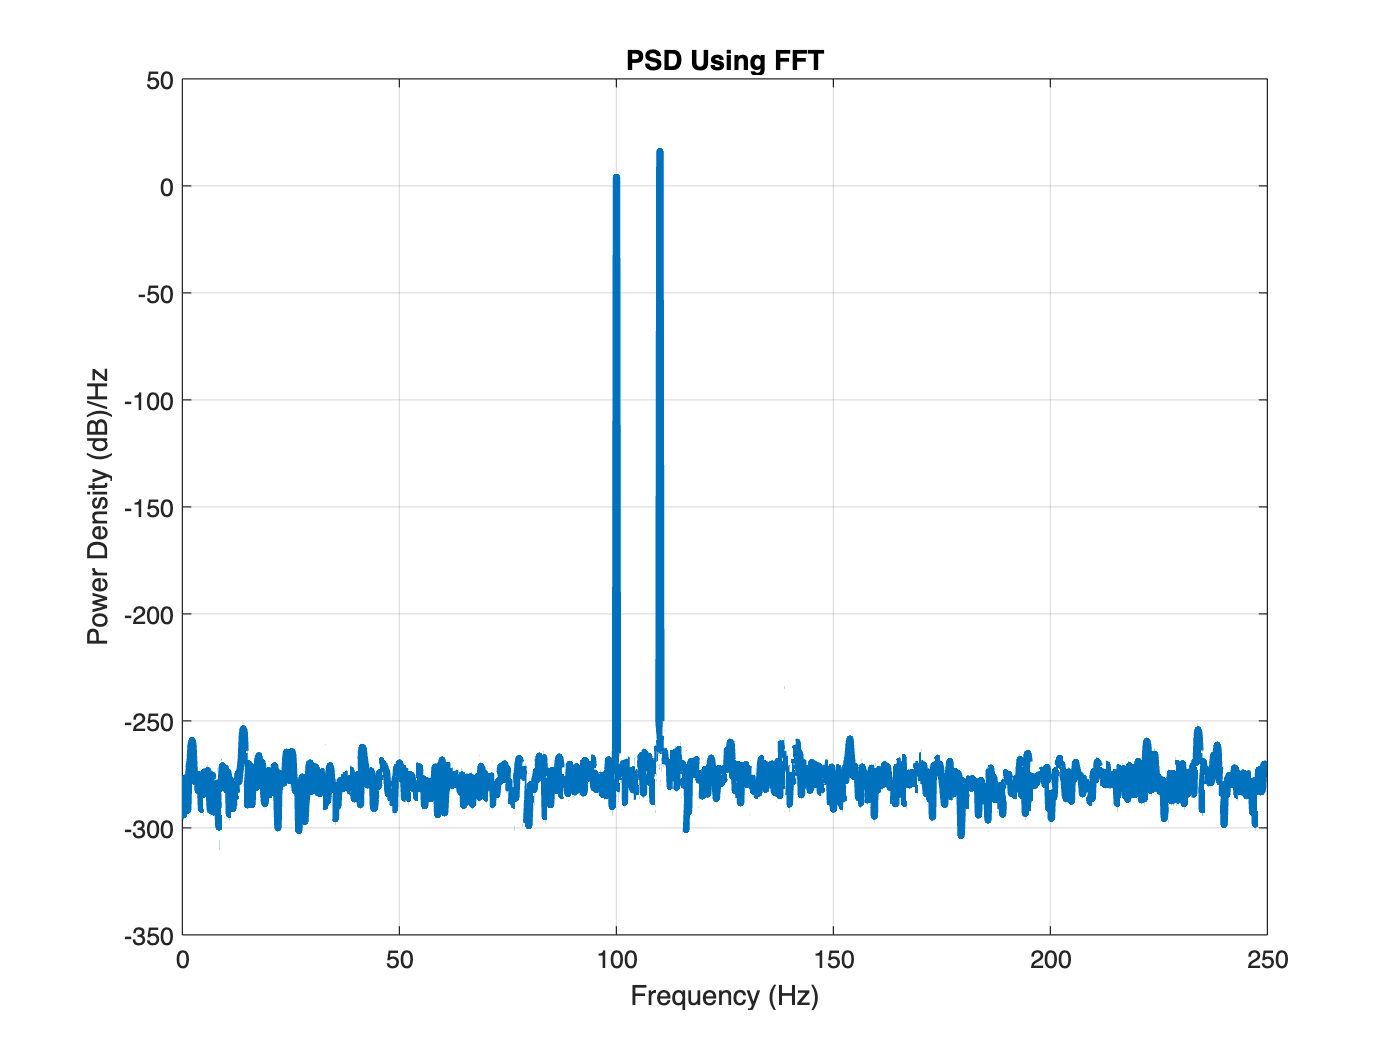

xk = (1/(fs*N))*abs(fft(xn)).^2; % Two-sided power
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),pow2db(xk), 'LineWidth', 3)
grid on
title("PSD Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power Density (dB)/Hz")

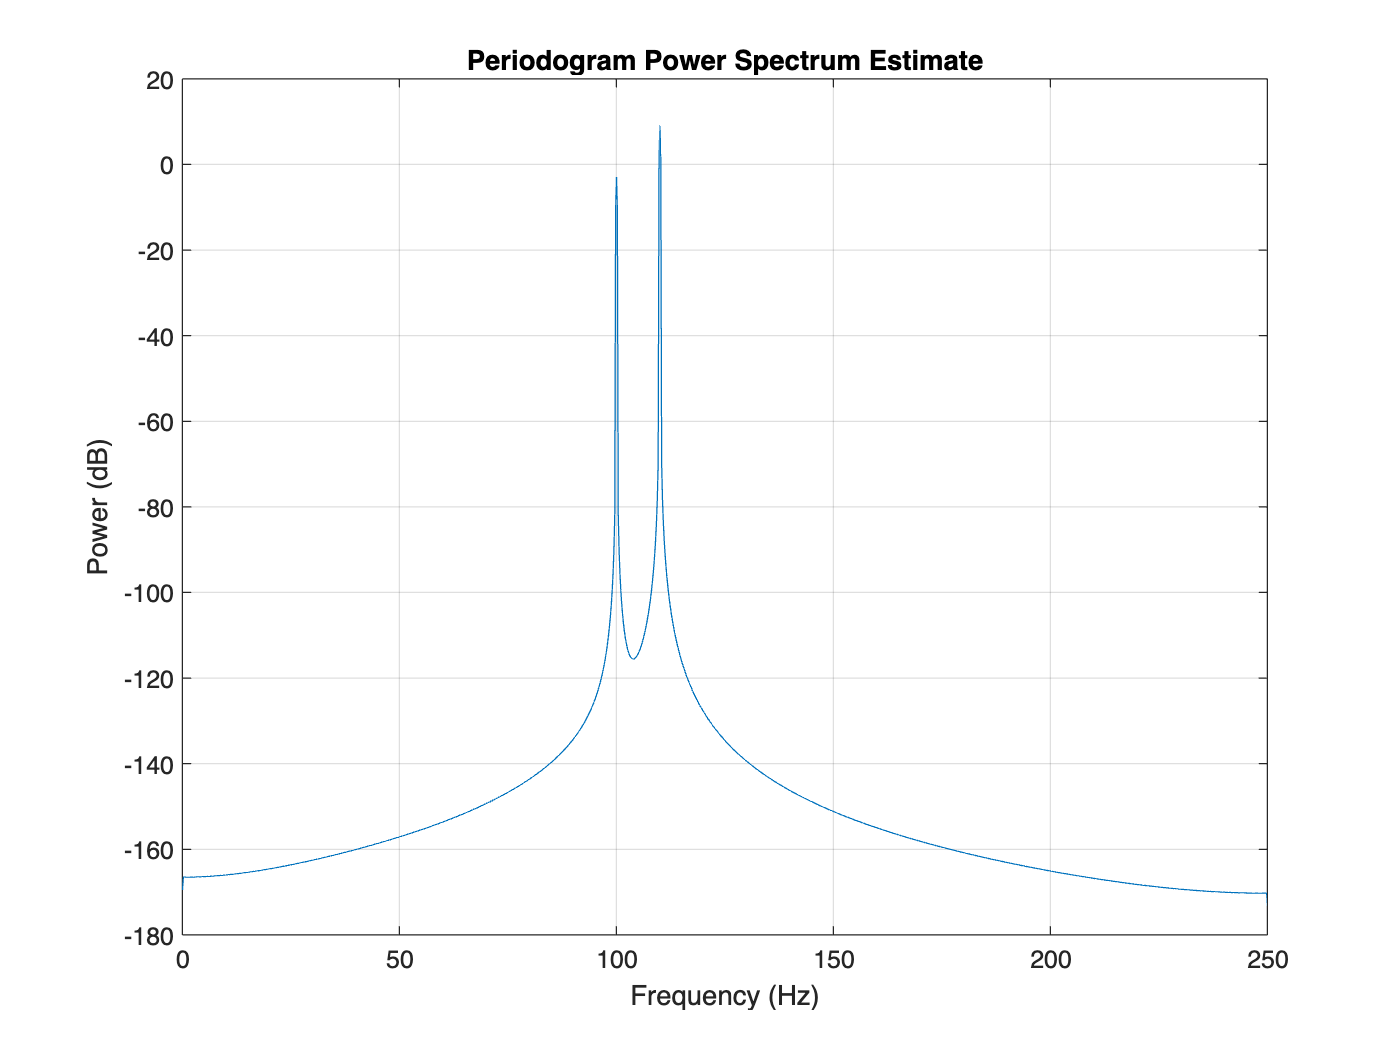

periodogram(xn, hamming(length(xn)), length(xn), fs, 'power');